# Plot Figure 2 - supplementary 7

## Add path

addpath(genpath('../public_code'))


addpath(genpath('~/MyDocuments/physics/projects/maxent/UGM'))
addpath(genpath('~/MyDocuments/physics/projects/social_mice'))

cd('~/MyDocuments/physics/projects/social_mice/output/train_test_l2_240712/')



% nstrain_c57_set = {'male_before_timp_180511', ...
%                    'male_c57_181012', ...
%                    'male_c57_200701', ...
%                    'male_before_bsa_200713'};
% 
% 
% ttscheme = '1h';  ntest = 6; nNodes = 15; nStates = 4;
% jij2_alldata = {};
% hir2_alldata = {};
% %%
% s3 = {};
% 
% didf2 = [0, 4; 5, 9];
% count = 0;
% for i = 1:4 
%     nstrain = nstrain_c57_set{i};
%     for j = 1:2
% 
%         disp(['i = ' num2str(i) ', j = ' num2str(j)])
%         count = count + 1; 
%         di = didf2(j,1);
%         df = didf2(j,2);
% 
%         sub_flag = 0;
%         s2 = my_load_data(nstrain, di, df, sub_flag);
% 
%         s3{count} = s2;
%         %%
%         fp = ['sme_pairwise_l2_' nstrain '_di' num2str(di) ...
%             '_df' num2str(df) '_' ttscheme '_beta0.mat'];
%         load(fp,'jijFinal_alldata','hirFinal_alldata',...
%             'jijFinal3','hirFinal3');
% 
%         jij2_alldata{count} = jijFinal_alldata;
%         hir2_alldata{count} = hirFinal_alldata;
%    
% 
%     end
% end



nstrain_c57_set = {'male_before_timp_180511', ...
                   'male_c57_181012', ...
                   'male_c57_200701', ...
                   'male_before_bsa_200713'};

ttscheme = '1h';
% di = 0; df = 4;
didf2 = [0, 4; 5, 9];

count = 0;
x_jij = [];
y_jij = [];
x_hir = [];
y_hir = [];
mean_jij = [];
mean_jij_bs = [];
std_jij = [];
std_jij_bs = [];

mean_hir = [];
mean_hir_bs = [];
std_hir = [];
std_hir_bs = [];

for i = 1:4
    nstrain = nstrain_c57_set{i};
    for j = 1:2

        count = count + 1; 
        di = didf2(j,1);
        df = didf2(j,2);

        %%
        fp = ['sme_pairwise_l2_' nstrain '_di' num2str(di) ...
            '_df' num2str(df) '_' ttscheme '_beta0.mat'];
        load(fp,'jijFinal_alldata','hirFinal_alldata',...
            'jijFinal3','hirFinal3');
        %%

        x_jij = [x_jij ones(1, length(jijFinal_alldata))*count];
        y_jij = [y_jij jijFinal_alldata'];

        mean_jij = [mean_jij mean(jijFinal_alldata)];
        std_jij = [std_jij std(jijFinal_alldata)];

        mean_jij_bs = [mean_jij_bs  mean(jijFinal3)'];
        std_jij_bs = [std_jij_bs  std(jijFinal3)'];

        %%
        x_hir = [x_hir ones(1, length(hirFinal_alldata))*count];

        y_hir = [y_hir hirFinal_alldata'];

        mean_hir = [mean_hir mean(hirFinal_alldata)];
        std_hir = [std_hir std(hirFinal_alldata)];

        mean_hir_bs = [mean_hir_bs  mean(hirFinal3)'];
        std_hir_bs = [std_hir_bs  std(hirFinal3)'];
    end
end


%%
jij3 = {y_jij(1:105), y_jij(106:210), y_jij(211:288), ...
     y_jij(289:366), y_jij(367:411), y_jij(412:456), ...
     y_jij(457:522), y_jij(523:588)};

hir3 = {y_hir(1:45), y_hir(46:90), y_hir(91:129), ...
     y_hir(130:168), y_hir(169:198), y_hir(199:228), ...
     y_hir(229:264), y_hir(265:300)};

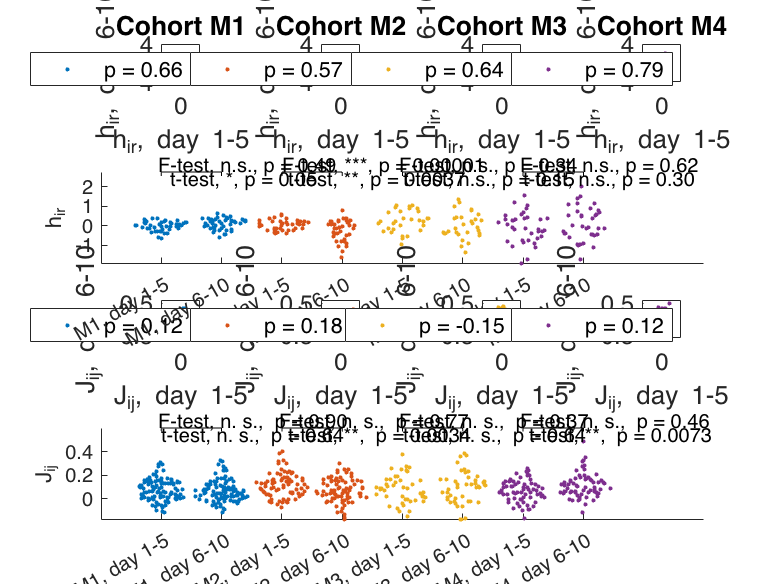



nNodes2 = [15, 13, 10, 12, 15];

matlab_color = [0 114 189;
                217 83 25;
                237 177 32;
                126 47 142]/256;

figure()

ne_start = 1;
nh_start = 1;

pt_hir2 = [];
pf_hir2 = [];
pt_jij2 = [];
pf_jij2 = [];

for icohort = 1:4

    nNodes = nNodes2(icohort);
    nh = nNodes*3;
    ne = nNodes*(nNodes-1)/2;
    nh_end = nh_start + nh*2 - 1;
    ne_end = ne_start + ne*2 - 1;


    subplot(4,4,icohort)
    plot(hir3{(icohort-1)*2+1}, hir3{(icohort-1)*2+2},'.',...
        'color',matlab_color(icohort,:))
    l=legend(['p = ' ...
        num2str(corr(hir3{(icohort-1)*2+1}', ...
        hir3{(icohort-1)*2+2}'),'%.2f')]);
    l.Location = 'southeast';
    xlabel('h_{ir}, day 1-5')
    ylabel('h_{ir}, day 6-10')
    axis([-1 1 -1 1]*4)
    axis square
    set(gca,'fontsize',12)
    title(['Cohort M' num2str(icohort)])

    subplot(4,4,icohort+8)
    plot(jij3{(icohort-1)*2+1}, jij3{(icohort-1)*2+2},'.',...
        'color',matlab_color(icohort,:))
    l=legend(['p = ' ...
        num2str(corr(jij3{(icohort-1)*2+1}', ...
         jij3{(icohort-1)*2+2}'),'%.2f')]);
    l.Location='southeast';
    xlabel('J_{ij}, day 1-5')
    ylabel('J_{ij}, day 6-10')
    axis square
    axis([-1 1 -1 1]*0.6)
%     axis([-0.2 0.6 -0.2 0.6])
    set(gca,'fontsize',12)

    subplot(4,1,2)
    swarmchart(x_hir(nh_start:nh_end),...
        y_hir(nh_start:nh_end),'.');
    nh_start = nh_end + 1;
    hold on
    
%     text(1.45,0.43,txt)
    
    ylabel('h_{ir}')

    [~,pt] = ttest2(hir3{(icohort-1)*2+1},hir3{(icohort-1)*2+2});
    [~,pf] = vartest2(hir3{(icohort-1)*2+1},hir3{(icohort-1)*2+2});
    

    [pt_hir2] = [pt_hir2 pt];
    [pf_hir2] = [pf_hir2 pf];

    subplot(4,1,4)
    swarmchart(x_jij(ne_start:ne_end),...
        y_jij(ne_start:ne_end),'.');
    ne_start = ne_end + 1;
    hold on
    ylabel('J_{ij}')

    [~,pt] = ttest2(jij3{(icohort-1)*2+1},jij3{(icohort-1)*2+2});
    [~,pf] = vartest2(jij3{(icohort-1)*2+1},jij3{(icohort-1)*2+2});

    [pt_jij2] = [pt_jij2 pt];
    [pf_jij2] = [pf_jij2 pf];


end



subplot(4,1,2)
for icohort = 1:4
    plot([(icohort-1)*2+1,icohort*2],[2.75, 2.75],'k')
    plot([(icohort-1)*2+1,(icohort-1)*2+1],[2.55, 2.75],'k')
    plot([icohort*2,icohort*2],[2.55, 2.75],'k')
    if pf_hir2(icohort) > 0.05
        txt = {['F-test, n.s., p = ' num2str(pf_hir2(icohort), '%.2f')]};
        text((icohort-1)*2+0.95,3.1,txt)
    elseif pf_hir2(icohort) > 0.01
        txt = {['F-test, *, p = ' num2str(pf_hir2(icohort), '%.2f')]};
        text((icohort-1)*2+1.,3.1,txt)
    elseif pf_hir2(icohort) > 0.001
        txt = {['F-test, **, p = ' num2str(pf_hir2(icohort), '%.2f')]};
        text((icohort-1)*2+1.1,3.1,txt)
    else 
        txt = {['F-test, ***, p = ' num2str(pf_hir2(icohort), '%.5f')]};
        text((icohort-1)*2+1.,3.1,txt)
    end

    if pt_hir2(icohort) > 0.05
        txt = {['t-test, n.s., p = ' num2str(pt_hir2(icohort), '%.2f')]};
        text((icohort-1)*2+1.,2.4,txt)
    elseif pt_hir2(icohort) > 0.01
        txt = {['t-test, *, p = ' num2str(pt_hir2(icohort), '%.2f')]};
        text((icohort-1)*2+1.15,2.4,txt)
    elseif pt_hir2(icohort) > 0.001
        txt = {['t-test, **, p = ' num2str(pt_hir2(icohort), '%.4f')]};
        text((icohort-1)*2+1.1,2.4,txt)
    end

    xticks([1 2 3 4 5 6 7 8 ])
    xticklabels({'M1, day 1-5', 'M1, day 6-10', ...
                 'M2, day 1-5', 'M2, day 6-10', ...
                 'M3, day 1-5', 'M3, day 6-10', ...
                 'M4, day 1-5', 'M4, day 6-10'})
end



subplot(4,1,4)
for icohort = 1:4
    plot([(icohort-1)*2+1,icohort*2],[0.6, 0.6],'k')
    plot([(icohort-1)*2+1,(icohort-1)*2+1],[0.57, 0.6],'k')
    plot([icohort*2,icohort*2],[0.57, 0.6],'k')
    if pf_jij2(icohort) > 0.05
        txt = {['F-test, n. s.,  p = ' num2str(pf_jij2(icohort), '%.2f')]};
        text((icohort-1)*2+0.95,0.66,txt)
    elseif pf_jij2(icohort) > 0.01
        txt = {'F-test, *'};
        text((icohort-1)*2+1.,0.66,txt)
    elseif pf_jij2(icohort) > 0.001
        txt = {'F-test, **'};
        text((icohort-1)*2+1.,0.66,txt)
    else 
        txt = {'F-test, ***'};
        text((icohort-1)*2+1.,0.66,txt)
    end

    if pt_jij2(icohort) > 0.05
        txt = {['t-test, n. s.,  p = ' num2str(pt_jij2(icohort), '%.2f')]};
        text((icohort-1)*2+1.,0.54,txt)
    elseif pt_jij2(icohort) > 0.01
        txt = {'t-test, *'};
        text((icohort-1)*2+1.,0.54,txt)
    elseif pt_jij2(icohort) > 0.001
        txt = {['t-test, **,  p = ' num2str(pt_jij2(icohort), '%.4f')]};
        text((icohort-1)*2+1.1,0.54,txt)
    end
    xticks([1 2 3 4 5 6 7 8 ])
    xticklabels({'M1, day 1-5', 'M1, day 6-10', ...
                 'M2, day 1-5', 'M2, day 6-10', ...
                 'M3, day 1-5', 'M3, day 6-10', ...
                 'M4, day 1-5', 'M4, day 6-10'})
end